%Revista Applied Sciences (MDPI)
%Comparativa de diferentes criterios para ordenar las dinámicas
%Rapidez, Ganancia estática, Residuo, Lentitud
% en el reparto interlacing N=6
%Aplicación: Vehiculo
% salida yaw rate entrada steering
% El control está diseñado para considerar una velocidad lineal entre 4 y 20 m/s (circuito urbano)
%Regulador diseñado en continuo con H_inf más agresivo para modelo vehículo de Zhang
%El regulador discreto se separa en 9 Dinámicas: 4 complejos + 5 reales
%En la forma digonal son sistemas de S1 a S9

clear;
close all;

N=6;%Orden interlacing

%System parameters
m=995;
a=1.233;
b=1.327;
Caf=41e3;
l=2.56;
Iz=1760;
Car=47e3;
g = 9.81;
%vx=6;%Regulador suave
%Vx=10;%Regulador agresivo
vx = ureal('vx',10,'Range',[4,20]);%Ha aumentado el rango de 10 a 20
a1=m*vx*a*Caf;
a2=l*Caf*Car;
b1=m*vx*Iz;
b2=Iz*(Caf+Car)+m*((a^2)*Caf+(b^2)*Car);
b3=(Caf*Car/vx)*(l^2)*(1+((m*vx*(b*Car-a*Caf))/(Caf*Caf*(l^2))));
s=tf('s');

p=(a1*s+a2)/(b1*s^2+b2*s+b3)%Proceso Continuo con incertidumbre

Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 8 states.
The model uncertainty consists of the following blocks:
  vx: Uncertain real, nominal = 10, range = [4,20], 4 occurrences
Model Properties


%analisis
Planta=tf(p) %Planta nominal


Planta =
 
     28.72 s + 281.7
  ---------------------
  s^2 + 17.09 s + 72.88
 
Continuous-time transfer function.
Model Properties


disp('Polos:'),pole(Planta)

Polos:


ans =    -8.8872
   -8.2011


disp('Ceros:'),tzero(p)

Ceros:


ans = -9.8073


%Perido de muestreo
T=10e-3;%10ms

load('regmu_cochezhang')

%K: regulador continuo de orden 13
%Kred: regulador continuo de orden 4
Kred=balred(K,4);
Kred2=balred(K,1);%mantiene el integrador

BC1=minreal(K*Planta/(1+K*Planta));

16 states removed.


BC2=minreal(Kred*Planta/(1+Kred*Planta));

7 states removed.


BC3=minreal(Kred*Planta/(1+Kred2*Planta));

4 states removed.


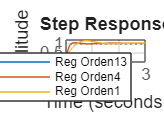



figure,step(BC1,BC2,BC3),legend('Reg Orden13','Reg Orden4', 'Reg Orden1'),grid

%No hay diferencias apreciables: Esto es indicativo de que el interlacing
%tendrá buenos resultados. En realidad si se reduce el orden es menos
%costoso computacionalmente que el interlacing ***********

Gr=c2d(K,T,'zoh');
Reg=ss(Gr);
SR_Diag=canon(Reg,'modal')


SR_Diag =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10       x11       x12       x13
   x1     0.1002         0         0         0         0         0         0         0         0         0         0         0         0
   x2          0    0.6648    0.1448         0         0         0         0         0         0         0         0         0         0
   x3          0   -0.1448    0.6648         0         0         0         0         0         0         0         0         0         0
   x4          0         0         0    0.8009    0.1105         0         0         0         0         0         0         0         0
   x5          0         0         0   -0.1105    0.8009         0         0         0         0         0         0         0         0
   x6          0         0         0         0         0    0.9031   0.03557         0         0         0         0         0         0
   x7          0     

[pole(SR_Diag) abs(pole(SR_Diag))] %No Ordenados de rápido a lento

ans =    0.9839 + 0.0316i   0.9844 + 0.0000i
   0.9839 - 0.0316i   0.9844 + 0.0000i
   0.6648 + 0.1448i   0.6804 + 0.0000i
   0.6648 - 0.1448i   0.6804 + 0.0000i
   0.8009 + 0.1105i   0.8084 + 0.0000i
   0.8009 - 0.1105i   0.8084 + 0.0000i
   0.9031 + 0.0356i   0.9038 + 0.0000i
   0.9031 - 0.0356i   0.9038 + 0.0000i
   0.1002 + 0.0000i   0.1002 + 0.0000i
   0.9057 + 0.0000i   0.9057 + 0.0000i



%Ordenador polos de mayor a menor rapidez
[RegDiag_sep]=regdiagsep(SR_Diag, [1 2 2 2 1 1 1 2 1]);%separar todos los subespacios
S1=RegDiag_sep.S1;
p1=pole(S1)%p1=pole(SR_Diag.A(1,1))

p1 = 0.1002

pole(c2d(Kred2,T))

ans = 1.0000


S2=RegDiag_sep.S2;
p2p3=pole(S2)%=eig(SR_Diag.A(2:3,2:3))

p2p3 =    0.6648 + 0.1448i
   0.6648 - 0.1448i


S3=RegDiag_sep.S3;
p4p5=pole(S3)%p4p5=eig(SR_Diag.A(4:5,4:5))

p4p5 =    0.8009 + 0.1105i
   0.8009 - 0.1105i


S4=RegDiag_sep.S4;
p6p7=pole(S4)%p6p7=eig(SR_Diag.A(6:7,6:7))

p6p7 =    0.9031 + 0.0356i
   0.9031 - 0.0356i


S5=RegDiag_sep.S5;
p8=pole(S5)%p8=eig(SR_Diag.A(8,8))

p8 = 0.9057

S6=RegDiag_sep.S6;
p9=pole(S6)%p9p10=eig(SR_Diag.A(9:10,9:10))

p9 = 0.9657

S7=RegDiag_sep.S7;
p10=pole(S7)%p11=eig(SR_Diag.A(11,11))

p10 = 0.9723

S8=RegDiag_sep.S8;
p11p12=pole(S8)%p12=eig(SR_Diag.A(12,12))

p11p12 =    0.9839 + 0.0316i
   0.9839 - 0.0316i


S9=RegDiag_sep.S9;
p13=pole(S9)%p13=eig(SR_Diag.A(13,13))

p13 = 1.0000

%9 Dinámicas: 4 complejos + 5 reales
%En la forma digonal son sistemas de S1 a S9




%Analisis de las 9 dinamicas
disp('[polo abs c*b ganancia]')

[polo abs c*b ganancia]


comp=[p1 abs(p1) norm(S1.C*S1.B) dcgain(S1)
 p2p3(1) abs(p2p3(1)) norm(S2.C*S2.B) dcgain(S2)
 p4p5(1) abs(p4p5(1)) norm(S3.C*S3.B(1,:)) dcgain(S3)
 p6p7(1) abs(p6p7(1)) norm(S4.C*S4.B(1,:)) dcgain(S4)
 p8 abs(p8) norm(S5.C*S5.B) dcgain(S5)
 p9 abs(p9) norm(S6.C*S6.B(1,:)) dcgain(S6)
 p10 abs(p10) norm(S7.C*S7.B) dcgain(S7)
 p11p12(1) abs(p11p12(1)) norm(S8.C*S8.B) dcgain(S8)
 p13 abs(p13) norm(S9.C*S9.B) dcgain(S9)]

comp = 1.0e+02 *

   0.0010 + 0.0000i   0.0010 + 0.0000i   0.0042 + 0.0000i   0.0046 + 0.0000i
   0.0066 + 0.0014i   0.0068 + 0.0000i   0.0000 + 0.0000i  -0.0001 + 0.0000i
   0.0080 + 0.0011i   0.0081 + 0.0000i   0.0001 + 0.0000i  -0.0003 + 0.0000i
   0.0090 + 0.0004i   0.0090 + 0.0000i   0.0000 + 0.0000i   0.0001 + 0.0000i
   0.0091 + 0.0000i   0.0091 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0097 + 0.0000i   0.0097 + 0.0000i   0.0000 + 0.0000i   0.0003 + 0.0000i
   0.0097 + 0.0000i   0.0097 + 0.0000i   0.0000 + 0.0000i   0.0004 + 0.0000i
   0.0098 + 0.0003i   0.0098 + 0.0000i   0.0001 + 0.0000i   0.0061 + 0.0000i
   0.0100 + 0.0000i   0.0100 + 0.0000i   0.0003 + 0.0000i   8.9236 + 0.0000i



%Ordenados por rapidez: abs(pi)
%[p1 p2p3 p4p5 p6p7 p8  p9  p10 p11p12 p13]
%S1,  S2,  S3,  S4, S5, S6, S7,  S8,    S9

%Ordenados por residuo: norm(ci*bi) 
%[p1 p13 p11p12 p6p7 p4p5 p10 p9 p2p3 p8]
%S1 – S9 – S8 – S4 – S3 – S7 – S6 – S2 – S5
%Rap: S1, S9,
nr=2;%2 reales
%Len1: S8 %complejo
%Len2: S4 %complejol
%Len3: S3, %complejo
%Len4: S7, S6 %real+real
%Len5: S2 %complejol
%Len6: S5, %real
nl=[2 2 2 2 2 1];
%Reduce el orden de 13 a 4-3
RegDiagC_Rap=ss(blkdiag(RegDiag_sep.S1.A,RegDiag_sep.S9.A),[RegDiag_sep.S1.B;RegDiag_sep.S9.B],[RegDiag_sep.S1.C RegDiag_sep.S9.C],0,T);
RegDiagC_Len1=ss(RegDiag_sep.S8.A,RegDiag_sep.S8.B,RegDiag_sep.S8.C,0,T);
RegDiagC_Len1_ext=d2d(RegDiagC_Len1,N*T);
RegDiagC_Len2=ss(RegDiag_sep.S4.A,RegDiag_sep.S4.B,RegDiag_sep.S4.C,0,T);
RegDiagC_Len2_ext=d2d(RegDiagC_Len2,N*T);
RegDiagC_Len3=ss(RegDiag_sep.S3.A,RegDiag_sep.S3.B,RegDiag_sep.S3.C,0,T);
RegDiagC_Len3_ext=d2d(RegDiagC_Len3,N*T);
RegDiagC_Len4=ss(blkdiag(RegDiag_sep.S7.A,RegDiag_sep.S6.A),[RegDiag_sep.S7.B;RegDiag_sep.S6.B],[RegDiag_sep.S7.C RegDiag_sep.S6.C],0,T);
RegDiagC_Len4_ext=d2d(RegDiagC_Len4,N*T);
RegDiagC_Len5=ss(RegDiag_sep.S2.A,RegDiag_sep.S2.B,RegDiag_sep.S2.C,0,T);
RegDiagC_Len5_ext=d2d(RegDiagC_Len5,N*T);
RegDiagC_Len6=ss(RegDiag_sep.S5.A,RegDiag_sep.S5.B,RegDiag_sep.S5.C,0,T);
RegDiagC_Len6_ext=d2d(RegDiagC_Len6,N*T);


%Ordenados por ganancia estática: dcgain(Si)
%[p13 p11p12 p1 p10 p4p5 p9 p2p3 p6p7 p8]
%S9, S8, S1, S7, S3, S6, S2, S4, S5
%Rap: S9, S8,
nr=3;%1 reales y 2 complejos
%Len1: S1, S7, %reales
%Len2: S3, %complejo
%Len3: S6 %real
%Len4: S5, %real
%Len5: S2, %complejo
%Len6: S4, %complejo
nl=[2 2 1 1 2 2];
%Reduce el orden de 13 a 5-4
RegDiagB_Rap=ss(blkdiag(RegDiag_sep.S9.A,RegDiag_sep.S8.A),[RegDiag_sep.S9.B;RegDiag_sep.S8.B],[RegDiag_sep.S9.C RegDiag_sep.S8.C],0,T);
RegDiagB_Len1=ss(blkdiag(RegDiag_sep.S1.A,RegDiag_sep.S7.A),[RegDiag_sep.S1.B;RegDiag_sep.S7.B],[RegDiag_sep.S1.C RegDiag_sep.S7.C],0,T);
RegDiagB_Len1_ext=d2d(RegDiagB_Len1,N*T);
RegDiagB_Len2=ss(RegDiag_sep.S3.A,RegDiag_sep.S3.B,RegDiag_sep.S3.C,0,T);
RegDiagB_Len2_ext=d2d(RegDiagB_Len2,N*T);
RegDiagB_Len3=ss(RegDiag_sep.S6.A,RegDiag_sep.S6.B,RegDiag_sep.S6.C,0,T);
RegDiagB_Len3_ext=d2d(RegDiagB_Len3,N*T);
RegDiagB_Len4=ss(RegDiag_sep.S5.A,RegDiag_sep.S5.B,RegDiag_sep.S5.C,0,T);
RegDiagB_Len4_ext=d2d(RegDiagB_Len4,N*T);
RegDiagB_Len5=ss(RegDiag_sep.S2.A,RegDiag_sep.S2.B,RegDiag_sep.S2.C,0,T);
RegDiagB_Len5_ext=d2d(RegDiagB_Len5,N*T);
RegDiagB_Len6=ss(RegDiag_sep.S4.A,RegDiag_sep.S4.B,RegDiag_sep.S4.C,0,T);
RegDiagB_Len6_ext=d2d(RegDiagB_Len6,N*T);

%Ordenados por rapidez al reves (primero el más lento)
%Rap: S8, S9 %complejo+real
%Len1: S6, S7, %reales
%Len2: S5 real
%Len3: S4 %complejo
%Len4: S3 %complejo
%Len5: S2 %complejo
%Len6: S1 %real
nr=3

nr = 3

nl=[2 1 2 2 2 1];
%Reduce el orden de 13 a 5-4
RegDiagD_Rap=ss(blkdiag(RegDiag_sep.S8.A,RegDiag_sep.S9.A),[RegDiag_sep.S8.B;RegDiag_sep.S9.B],[RegDiag_sep.S8.C RegDiag_sep.S9.C],0,T);
RegDiagD_Len1=ss(blkdiag(RegDiag_sep.S6.A,RegDiag_sep.S7.A),[RegDiag_sep.S6.B;RegDiag_sep.S7.B],[RegDiag_sep.S6.C RegDiag_sep.S7.C],0,T);
RegDiagD_Len1_ext=d2d(RegDiagD_Len1,N*T);
RegDiagD_Len2=ss(RegDiag_sep.S5.A,RegDiag_sep.S5.B,RegDiag_sep.S5.C,0,T);
RegDiagD_Len2_ext=d2d(RegDiagD_Len2,N*T);
RegDiagD_Len3=ss(RegDiag_sep.S4.A,RegDiag_sep.S4.B,RegDiag_sep.S4.C,0,T);
RegDiagD_Len3_ext=d2d(RegDiagD_Len3,N*T);
RegDiagD_Len4=ss(RegDiag_sep.S3.A,RegDiag_sep.S3.B,RegDiag_sep.S3.C,0,T);
RegDiagD_Len4_ext=d2d(RegDiagD_Len4,N*T);
RegDiagD_Len5=ss(RegDiag_sep.S2.A,RegDiag_sep.S2.B,RegDiag_sep.S2.C,0,T);
RegDiagD_Len5_ext=d2d(RegDiagD_Len5,N*T);
RegDiagD_Len6=ss(RegDiag_sep.S1.A,RegDiag_sep.S1.B,RegDiag_sep.S1.C,0,T);
RegDiagD_Len6_ext=d2d(RegDiagD_Len6,N*T);


%Analisis modelo balanceado
[SR_Bal gr]=balreal(Gr)


SR_Bal =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13
   x1            1    0.000156  -0.0001831  -7.926e-06   7.356e-07  -3.142e-09   8.106e-07   1.457e-07   7.052e-09   5.868e-09   1.887e-08   1.055e-09  -9.864e-11
   x2     0.000156      0.7653      0.3846    -0.01711    -0.01202   9.514e-05    -0.01226    -0.00228  -0.0001102  -9.275e-05  -0.0002983  -1.666e-05   1.558e-06
   x3   -0.0001831      0.3846      0.3142     0.09362     0.03072   -0.000252     0.03113    0.005805   0.0002804   0.0002363   0.0007601   4.245e-05  -3.971e-06
   x4    7.926e-06     0.01711    -0.09362      0.9899   -0.005883   4.431e-05   -0.006049   -0.001121  -5.415e-05  -4.554e-05  -0.0001465  -8.181e-06   7.652e-07
   x5   -7.356e-07     0.01202    -0.03072   -0.005883      0.9028    -0.07437     -0.2279    -0.02104   -0.001059  -0.0006549   -0.002084  -0.0001191   1.108e-05
   

gr =   446.1896
    0.5678
    0.3704
    0.1933
    0.0027
    0.0025
    0.0009
    0.0001
    0.0001
    0.0000


disp('[polo gan]')

[polo gan]


[pole(SR_Bal) gr]

ans = 1.0e+02 *

   0.0010 + 0.0000i   4.4619 + 0.0000i
   0.0066 + 0.0014i   0.0057 + 0.0000i
   0.0066 - 0.0014i   0.0037 + 0.0000i
   0.0080 + 0.0011i   0.0019 + 0.0000i
   0.0080 - 0.0011i   0.0000 + 0.0000i
   0.0090 + 0.0004i   0.0000 + 0.0000i
   0.0090 - 0.0004i   0.0000 + 0.0000i
   0.0091 + 0.0000i   0.0000 + 0.0000i
   0.0100 + 0.0000i   0.0000 + 0.0000i
   0.0098 + 0.0003i   0.0000 + 0.0000i


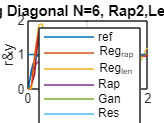

%gr es el gramiano asociado a los estados balanceados,
%Faltaria trasladar este indice a los modos (ver para cada estado
%balanceado como efectan los modos de la diagonal.

%Sistema diagonal ordenado por rapidez
Ad=blkdiag(S1.A,S2.A,S3.A,S4.A,S5.A,S6.A,S7.A,S8.A,S9.A);
Bd=[S1.B;S2.B;S3.B;S4.B;S5.B;S6.B;S7.B;S8.B;S9.B];
Cd=[S1.C S2.C S3.C S4.C S5.C S6.C S7.C S8.C S9.C];
Sd=ss(Ad,Bd,Cd,Gr.D,T);
[sysbal,sigma,TL,TR] = balreal(Sd);
%TL matriz de transformación para pasar a sysbal 

% sigma: HSV globales, ordenados de mayor a menor
% TR: coordenadas balanceadas -> coordenadas modales
% blks: dimensiones de los bloques modales
blks = [1 2 2 2 1 1 1 2 1];%Dimensiones de los bloques modales

hbal = zeros(numel(blks),1);
ini  = 1;
for i = 1:numel(blks)
    idx = ini:(ini + blks(i) - 1);

    alpha = sum(abs(TR(idx,:)).^2,1) ./ sum(abs(TR).^2,1);

    hbal(i) = alpha * sigma(:);

    ini = ini + blks(i);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%Equivale a [Si_bal hi(i)]=balreal(Si) 
blks = [1 2 2 2 1 1 1 2 1];%Orden de los bloques modales
Wc = dlyap(Ad, Bd*Bd');
Wo = dlyap(Ad', Cd'*Cd);
nK = sum(blks);
I  = eye(nK);
ini = 1;
for i = 1:numel(blks)
    ni = blks(i);
    idx = ini:(ini + ni - 1);
    Ei = I(:,idx);
    Wcii = Ei' * Wc * Ei;
    Woii = Ei' * Wo * Ei;
    hi(i) = sqrt(max(real(eig(Wcii * Woii))));
    ini = ini + ni;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



%Ordenados por gr (gramiano)
%[p1 p2p3 p4p5 p6p7 p8 p13 p11p12 p10 p9]
%S1, S2, S3, S4, S5, S9, S8, S7, S6 
%Rap: S1, S2,%1 real+ 1 complejos
%Len1: S3 complejo
%Len2: S4, , %complejo
%Len3: S5, S9, %2 real
%Len4: S8 %complejo
%Len5: S7, %real
%Len6: S6 %real
% nr=3;%1 real+ 1 complejos
% nl=[2 2 2 2 1 1];
% %Reduce el orden de 13 a 5-4
% RegDiagE_Rap=ss(blkdiag(RegDiag_sep.S1.A,RegDiag_sep.S2.A),[RegDiag_sep.S1.B;RegDiag_sep.S2.B],[RegDiag_sep.S1.C RegDiag_sep.S2.C],0,T);
% RegDiagE_Len1=ss(RegDiag_sep.S3.A,RegDiag_sep.S3.B,RegDiag_sep.S3.C,0,T);
% RegDiagE_Len1_ext=d2d(RegDiagE_Len1,N*T);
% RegDiagE_Len2=ss(RegDiag_sep.S4.A,RegDiag_sep.S4.B,RegDiag_sep.S4.C,0,T);
% RegDiagE_Len2_ext=d2d(RegDiagE_Len2,N*T);
% RegDiagE_Len3=ss(blkdiag(RegDiag_sep.S5.A,RegDiag_sep.S9.A),[RegDiag_sep.S5.B;RegDiag_sep.S9.B],[RegDiag_sep.S5.C RegDiag_sep.S9.C],0,T);
% RegDiagE_Len3_ext=d2d(RegDiagE_Len3,N*T);
% RegDiagE_Len4=ss(RegDiag_sep.S8.A,RegDiag_sep.S8.B,RegDiag_sep.S8.C,0,T);
% RegDiagE_Len4_ext=d2d(RegDiagE_Len4,N*T);
% RegDiagE_Len5=ss(RegDiag_sep.S7.A,RegDiag_sep.S7.B,RegDiag_sep.S7.C,0,T);
% RegDiagE_Len5_ext=d2d(RegDiagE_Len5,N*T);
% RegDiagE_Len6=ss(RegDiag_sep.S6.A,RegDiag_sep.S6.B,RegDiag_sep.S6.C,0,T);
% RegDiagE_Len6_ext=d2d(RegDiagE_Len6,N*T);
% %Buen comportamiento, pero no tiene sentido físico: los valores singulares
% %de Hankel están asociados a estados y los modos influyen en todos los
% %estados

%Orden por índice ctrb-obsv relacionado con valores de Hankel trasladados a
%forma modal
%S9 – S1 – S8 – S4 – S3 – S7 – S2 – S6 – S5
%Rap: S9, S1,%2 reales
%Len1: S8 %complejo
%Len2: S4, %complejo
%Len3: S3, %complejo
%Len4: S7 %real
%Len5: S2, %complejo
%Len6: S6, S5 %2 reales
nr=2;%2 reales
nl=[2 2 2 1 2 2];
%Reduce el orden de 13 a 4-3
RegDiagE_Rap=ss(blkdiag(RegDiag_sep.S9.A,RegDiag_sep.S1.A),[RegDiag_sep.S9.B;RegDiag_sep.S1.B],[RegDiag_sep.S9.C RegDiag_sep.S1.C],0,T);
RegDiagE_Len1=ss(RegDiag_sep.S8.A,RegDiag_sep.S8.B,RegDiag_sep.S8.C,0,T);
RegDiagE_Len1_ext=d2d(RegDiagE_Len1,N*T);
RegDiagE_Len2=ss(RegDiag_sep.S4.A,RegDiag_sep.S4.B,RegDiag_sep.S4.C,0,T);
RegDiagE_Len2_ext=d2d(RegDiagE_Len2,N*T);
RegDiagE_Len3=ss(RegDiag_sep.S3.A,RegDiag_sep.S3.B,RegDiag_sep.S3.C,0,T);
RegDiagE_Len3_ext=d2d(RegDiagE_Len3,N*T);
RegDiagE_Len4=ss(RegDiag_sep.S7.A,RegDiag_sep.S7.B,RegDiag_sep.S7.C,0,T);
RegDiagE_Len4_ext=d2d(RegDiagE_Len4,N*T);
RegDiagE_Len5=ss(RegDiag_sep.S2.A,RegDiag_sep.S2.B,RegDiag_sep.S2.C,0,T);
RegDiagE_Len5_ext=d2d(RegDiagE_Len5,N*T);
RegDiagE_Len6=ss(blkdiag(RegDiag_sep.S6.A,RegDiag_sep.S5.A),[RegDiag_sep.S6.B;RegDiag_sep.S5.B],[RegDiag_sep.S6.C RegDiag_sep.S5.C],0,T);
RegDiagE_Len6_ext=d2d(RegDiagE_Len6,N*T);

%Ordenados por gri (i=1..9) (HVS de sistemas diagonales independientes) =
%parecido a ganancia
%[p13 p11p12 p1 p10 p4p5 p9  p6p7  p2p3  p8    ]
%S9 – S8 – S1 – S7 – S3 – S6 – S4 – S2 – S5
% %Rap: S9, S8 %real+complejo
% %Len1: S1, S7, %2real
% %Len2: S3,  %complejo
% %Len3: S6 %real
% %Len4: S4 %complejo
% %Len5: S2, %complejo
% %Len6: S5 %real
% nr=3;%1 real+ 1 complejos
% nl=[2 2 1 2 2 1];
% %Reduce el orden de 13 a 5-4
RegDiagG_Rap=ss(blkdiag(RegDiag_sep.S9.A,RegDiag_sep.S8.A),[RegDiag_sep.S9.B;RegDiag_sep.S8.B],[RegDiag_sep.S9.C RegDiag_sep.S8.C],0,T);
RegDiagG_Len1=ss(blkdiag(RegDiag_sep.S1.A,RegDiag_sep.S7.A),[RegDiag_sep.S1.B;RegDiag_sep.S7.B],[RegDiag_sep.S1.C RegDiag_sep.S7.C],0,T);
RegDiagG_Len1_ext=d2d(RegDiagG_Len1,N*T);
RegDiagG_Len2=ss(RegDiag_sep.S3.A,RegDiag_sep.S3.B,RegDiag_sep.S3.C,0,T);
RegDiagG_Len2_ext=d2d(RegDiagG_Len2,N*T);
RegDiagG_Len3=ss(RegDiag_sep.S6.A,RegDiag_sep.S6.B,RegDiag_sep.S6.C,0,T);
RegDiagG_Len3_ext=d2d(RegDiagG_Len3,N*T);
RegDiagG_Len4=ss(RegDiag_sep.S4.A,RegDiag_sep.S4.B,RegDiag_sep.S4.C,0,T);
RegDiagG_Len4_ext=d2d(RegDiagG_Len4,N*T);
RegDiagG_Len5=ss(RegDiag_sep.S2.A,RegDiag_sep.S2.B,RegDiag_sep.S2.C,0,T);
RegDiagG_Len5_ext=d2d(RegDiagG_Len5,N*T);
RegDiagG_Len6=ss(RegDiag_sep.S5.A,RegDiag_sep.S5.B,RegDiag_sep.S5.C,0,T);
RegDiagG_Len6_ext=d2d(RegDiagG_Len6,N*T);

%Prueba para N=6
GrN6=d2d(Gr,T*N);


%Forma diagonal


%Ordenados por rapidez
%Rap: S1, S2,
nr=3;%1 reales y  complejo
%Len1: S3 %complejo
%Len2: S4 %complejo
%Len3: S5, S6, %2 reales
%Len4: S7 % real
%Len5: S8 %complejo
%Len6: S9 % real
nl=[2 2 2 1 2 1];
%Reduce el orden de 13 a 5-4
%[RegDiag_sep]=regdiagsep(SR_Diag, [nr 2 2 2 2 2]);%separar subespacios
%No sirve porque no van por orden
RegDiagA_Rap=ss(blkdiag(RegDiag_sep.S1.A,RegDiag_sep.S2.A),[RegDiag_sep.S1.B;RegDiag_sep.S2.B],[RegDiag_sep.S1.C RegDiag_sep.S2.C],0,T);
RegDiagA_Len1=ss(RegDiag_sep.S3.A,RegDiag_sep.S3.B,RegDiag_sep.S3.C,0,T);
RegDiagA_Len1_ext=d2d(RegDiagA_Len1,N*T);
RegDiagA_Len2=ss(RegDiag_sep.S4.A,RegDiag_sep.S4.B,RegDiag_sep.S4.C,0,T);
RegDiagA_Len2_ext=d2d(RegDiagA_Len2,N*T);
RegDiagA_Len3=ss(blkdiag(RegDiag_sep.S5.A,RegDiag_sep.S6.A),[RegDiag_sep.S5.B;RegDiag_sep.S6.B],[RegDiag_sep.S5.C RegDiag_sep.S6.C],0,T);
RegDiagA_Len3_ext=d2d(RegDiagA_Len3,N*T);
RegDiagA_Len4=ss(RegDiag_sep.S7.A,RegDiag_sep.S7.B,RegDiag_sep.S7.C,0,T);
RegDiagA_Len4_ext=d2d(RegDiagA_Len4,N*T);
RegDiagA_Len5=ss(RegDiag_sep.S8.A,RegDiag_sep.S8.B,RegDiag_sep.S8.C,0,T);
RegDiagA_Len5_ext=d2d(RegDiagA_Len5,N*T);
RegDiagA_Len6=ss(RegDiag_sep.S9.A,RegDiag_sep.S9.B,RegDiag_sep.S9.C,0,T);
RegDiagA_Len6_ext=d2d(RegDiagA_Len6,N*T);



sim('N6Diag');
f=figure;
set(f,'Name','Interlacing Diagonal N=6, Rap2,Len2-2-2-2-2-1')
plot(datos.time,datos.signals.values),ylabel('r&y'),xlabel('Tiempo (s)'),grid
title('Interlacing Diagonal N=6, Rap2,Len2-2-2-2-2-1');
legend('ref','Reg_{rap}','Reg_{len}','Rap','Gan','Res', 'Lent','Gram','\sigma_d')

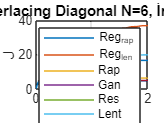

Y_A.time=datos.time;
Y_A.values=datos.signals.values(:,8);
f=figure;
set(f,'Name','Interlacing Diagonal N=6, Indices')
plot(Indices.time,Indices.signals.values),ylabel('J'),xlabel('Tiempo (s)'),grid
title('Interlacing Diagonal N=6, Índices');
legend('Reg_{rap}','Reg_{len}','Rap','Gan','Res', 'Lent','Gram','\sigma_d')

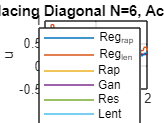


%Mejor comportamiento si ordenamos por mayor residuo
%si ordenamos por Hankel adaptado muy parecido a residuo


f=figure;
set(f,'Name','Interlacing Diagonal N=6, Acc.Control')
plot(Control.time,Control.signals.values),ylabel('u'),xlabel('Tiempo (s)'),grid
title('Interlacing Diagonal N=6, Acc.Control');
legend('Reg_{rap}','Reg_{len}','Rap','Gan','Res', 'Lent','h','\sigma_{Diag}')

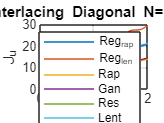


f=figure;
set(f,'Name','Interlacing Diagonal N=6, J_U')
plot(Ju.time,Ju.signals.values),ylabel('J_u'),xlabel('Tiempo (s)'),grid
title('Interlacing Diagonal N=5, J_U');
legend('Reg_{rap}','Reg_{len}','Rap','Gan','Res', 'Lent','h','\sigma_{Diag}')



%Valor final de los indices:
disp('Reg_{rap} - Reg_{len} - Rap - Gan - Res - Lent - h - \sigma_{Diag}')

Reg_{rap} - Reg_{len} - Rap - Gan - Res - Lent - h - \sigma_{Diag}


Indices.signals.values(length(Indices.signals.values),:)

ans =     4.5802   36.8692    6.2060   16.5591    4.7996   19.7612    4.8016   16.5064


Ju.signals.values(length(Ju.signals.values),:)

ans =    14.3597   29.3851   13.8572   20.7243   14.3624   21.1178   14.3609   20.6922




save('DatosN6.mat','datos');%Guardar datos para comparativa
save('ControlN6.mat','Control');%Guardar Acc.Control para comparativa
